# Linear Filtering

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-10

#### Identical Filter

img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = rgb2gray(imcrop(img, bbox));
patch = im2double(patch);
k1 = zeros(3,3);
k1(2,2) = 1;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(5:7)=1;
H = zeros(size(x)); H(6)=1;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig2,'Position', [100 100 800 250]);

#### Shifting Filter

k1 = zeros(3,3);
k1(2,3) = 1;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(5:7)=1;
H = zeros(size(x)); H(8)=1;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig2,'Position', [100 100 800 250]);

#### Blurring Filter

k1 = ones(3,3)/9;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(2:5)=1; F(6:end-1)=0.5;
H = zeros(size(x)); H(5:7)=1/3;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig2,'Position', [100 100 800 250]);

#### Shapening Filter

k1 = zeros(3,3);
k1(2,2)= 2;
k1 = k1 - ones(3,3)/9;

figure(11)
subplot(121); imshow(patch);
subplot(122); imshow(conv2(patch, k1, 'same'))

x = -5:1:5;
% G = H*F;
F = zeros(size(x)); F(:) = 1; F(1:4)=0.5; F(end-3:end)=0.5;
H = zeros(size(x)); H(5)=-1/3; H(7)=-1/3; H(6)=5/3;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(131);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(132);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([-1 2])
text(3, 1.5,'\bf H','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(133);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')
xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig2,'Position', [100 100 800 250]);

#### Understanding of a Sharpening Filter

x = -10:1:10;

% G = H*F;
F = zeros(size(x)); F(1:10) = 1; F(11:end)=0.5;
H = zeros(size(x)); H(10:12) = 1/3;
G = conv(F, H, 'same');

fig1 = figure(11);
ax1= subplot(231);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(232);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(233);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')

F_G = F-G; F_G(1) = 0; F_G(end) =0;
subplot(234);stem(x,F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([-.5 .5]);
text(0, 0.3,'\bf F - G','fontSize', 15, 'HorizontalAlignment', 'center')

alpha = 1;
subplot(235);stem(x,F+alpha*F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F + 1*(F-G)','fontSize', 15, 'HorizontalAlignment', 'center')

alpha = 2;
subplot(236);stem(x,F+alpha*F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.8,'\bf F + 2*(F-G)','fontSize', 15, 'HorizontalAlignment', 'center')

xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig1,'Position', [100 100 800 500]);

% G = H*F;
F = zeros(size(x)); F(1:end)=0.3; F(11) = 0.8;
H = zeros(size(x)); H(10:12) = 1/3;
G = conv(F, H, 'same');

fig2 = figure(12);
ax1= subplot(231);stem(x,F,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F','fontSize', 15, 'HorizontalAlignment', 'center')
ax2= subplot(232);stem(x,H,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf H','fontSize', 15, 'HorizontalAlignment', 'center')
ax3 = subplot(233);stem(x,G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2])
text(0, 1.5,'\bf G','fontSize', 15, 'HorizontalAlignment', 'center')

F_G = F-G; F_G(1) = 0; F_G(end) =0;
subplot(234);stem(x,F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([-.5 .5]);
text(0, 0.3,'\bf F - G','fontSize', 15, 'HorizontalAlignment', 'center')

alpha = 1;
subplot(235);stem(x,F+alpha*F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.5,'\bf F + 1*(F-G)','fontSize', 15, 'HorizontalAlignment', 'center')

alpha = 2;
subplot(236);stem(x,F+alpha*F_G,'linewidth',2);
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); ylim([0 2]);
text(0, 1.8,'\bf F + 2*(F-G)','fontSize', 15, 'HorizontalAlignment', 'center')

xlabel(ax2, '\bf X-axis');
ylabel(ax1, '\bf Y-axis'); 
set(fig2,'Position', [100 100 800 500]);

img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = rgb2gray(imcrop(img, bbox));
patch = im2double(patch);

k1 = zeros(3,3);
k1(2,2)= 2;
k1 = k1 - ones(3,3)/9;

figure(13)
subplot(231); imshow(patch);
G = imfilter(patch, fspecial('gaussian', 7, 1));
subplot(232); imshow(G);
patch_G = patch-G;
subplot(233); imshow(mat2gray(patch_G));
subplot(234); imshow(patch+(patch-G));
subplot(235); imshow(patch+5*(patch-G));


#### Gaussian Kernel

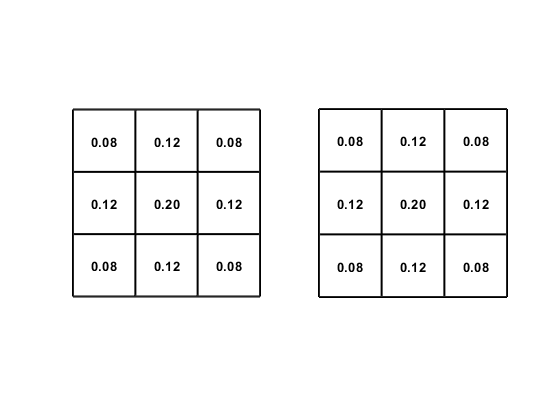

clear; close all; clc;

h = fspecial('gaussian',3,1);

numSize = 3;
[x, y] = meshgrid(1:numSize); 
x = x-(round(numSize/2));
y = y-(round(numSize/2));
sigma = 1;

G_sigma = 1/(2*pi*sigma^2)*exp(-(x.^2 + y.^2)/(2*sigma^2));
G_sigma = G_sigma/sum(G_sigma,'all');

figure(1); 
subplot(121); PlotMat(h,gca,'float');
subplot(122); PlotMat(G_sigma,gca,'float');

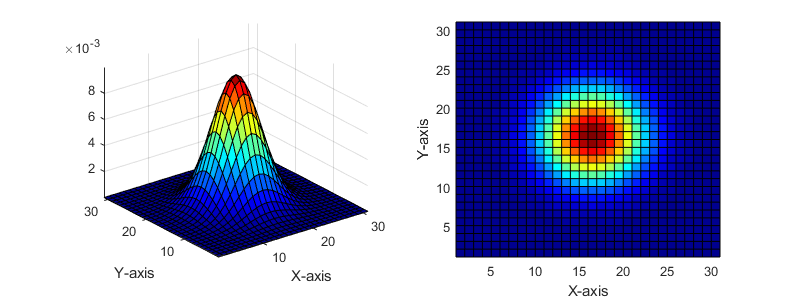


fig2 = figure(2);
subplot(121); h = fspecial('gaussian', 31,4);
surf(h); axis tight; colormap(jet)
set(fig2,'Position', [100 100 800 300]);
xlabel('X-axis'); ylabel('Y-axis');
subplot(122); surf(h); view(0,90);
xlabel('X-axis'); ylabel('Y-axis'); axis tight

#### Gaussian Filters

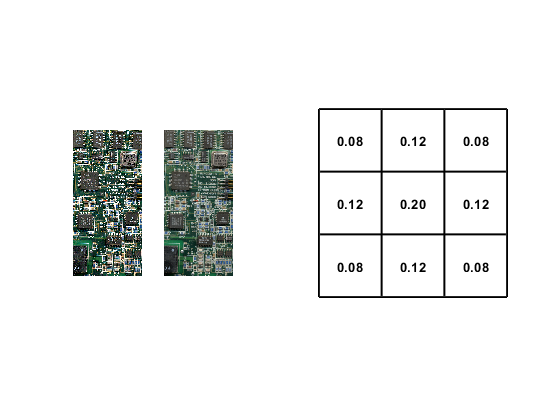

img = imread('board.tif');
bbox = [7.5100  152.5100  135.9800  142.9800];
patch = imcrop(img, bbox);

f1 =  fspecial('gaussian', 101,1);
f2 =  fspecial('gaussian', 101,5);
f3 =  fspecial('gaussian', 101,10);
f4 =  fspecial('gaussian', 101,30);

fig1 = figure(1);
subplot(151); imshow(img);
subplot(152); imshow(imfilter(img, f1));

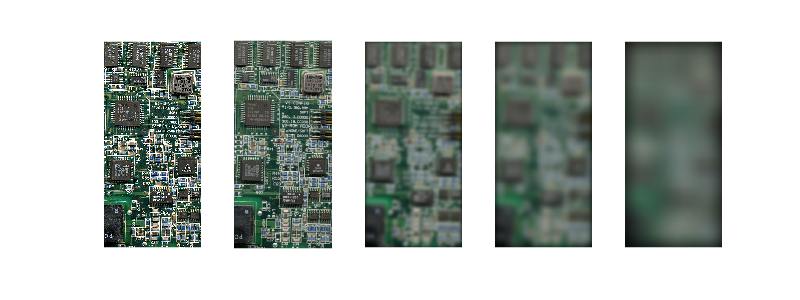

subplot(153); imshow(imfilter(img, f2));
subplot(154); imshow(imfilter(img, f3));
subplot(155); imshow(imfilter(img, f4));
set(fig1,'Position', [100 100 800 300]);

#### Gaussian Vs Box Filters

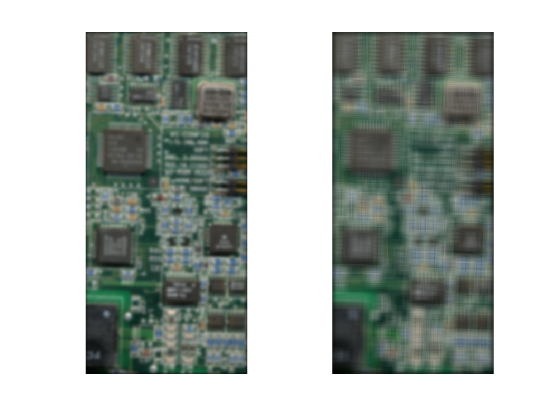

f1 = fspecial('gaussian', 19, 3);
f2 = fspecial('average', 19);

figure(3);
subplot(121); imshow(imfilter(img,f1));
subplot(122); imshow(imfilter(img,f2));